# Testing Pipeline 01.05.00

clear;
close;
clc;

%current path is always the folder storing the data folders or groups.
%   C:\Users\Vini\MATLAB Drive\John Studies Drive\analysis

## Get access to your current path

- **cd** => current directory 

- **dir** => lists files inside a folder

- we call our folders: groups

-     groups can be various settings or different circumstances of a recording, which later to be compared

%groupsRaw contains files and folders that are not part of our structure
groupsRaw = dir(cd); %get access to all files within the currentpath
addpath(genpath('mm'));
addpath(genpath('moderate'));
addpath(genpath('light'));
addpath(genpath('off'));
addpath(genpath('functions')); %add needed functions to the path

declare names that do not go into consideration for creation of group names

groups_struct = groupsRaw(~ismember({groupsRaw.name},{'.', '..','.MATLABDriveTag'...
    ,'data'...
    ,'AAF_Pipeline.mlx'...
    ,'functions'...
    ,'pipelineCurves.pdf'...
    ,'ignoreThisFolder'}));


## GROUPS

%store group member inside a cell array
groups = { groups_struct.name }';
groups = { groups{ 4 } ; groups{ 1 } ; groups{ 2 } ; groups{ 3 } };

clear groups_struct groupsRaw

## Set the used folders as your group structs 

- create a root struct.

- fill as many fields inside the root struct, as you see groups inside your groups cell array.

- eventually initialize them as structs as well.

- at last ***fetch your records*** as described below.

get access to .mat files inside the different groups using dir again this time with ****/*** accessing every single folder inside analysis (root)

- also store different fileNames inside a new cellArray called records, together with their group 

- fileNames is a combination of temp.name and temp.folder

- matlab acts weirldy when confronted with "-" instead of "_" so we have to change that as well  

## RECORDS

temp = dir('**/*.csv');
% analysis = setSubStructs(groups,true); %root

tempCell = cell(1,length(struct2table(temp).folder));

for joint_ind = 1:length(tempCell)

    tempCell{joint_ind} = append(struct2table(temp(joint_ind)).folder,"\",(temp(joint_ind).name));

end
%tempCell contains every records path
tempCell = tempCell';
clear joint_ind;

% records col 1:    contains group information
% records col 2:    contains full path information
% records col 3:    contains record name information
records = getPathProperties_2(tempCell,groups);

for joint_ind = 1:length(tempCell)

    records{joint_ind,2} = tempCell{joint_ind};
    records{joint_ind,3} = temp(joint_ind).name;

end
clear joint_ind temp tempCell;

## Biomechanic dictionary 

%mapValues = [1 2 3]; we mght want to map these names later?
joint_names = ["Knee", "Hip", "Ankle"];
sides =["RT", "LT"];
movementTypes = ["Flexion","Flexion","Dorsiflexion"];
contact_types = ["RT-Contact", "LT-Contact"];

## Channel names

channel names when using csv.single are constant

Contact_MP_LT =  'LT Contact_1';
Contact_MP_RT =  'RT Contact_1';
Contact_MM_LT =  'LT Contact';
Contact_MM_RT =  'RT Contact';

signalsToExtract = {'LT Knee Flexion (°)','LT Hip Flexion (°)','LT Ankle Dorsiflexion (°)','LT Knee Flexion (deg)' ,'LT Hip Flexion (deg)', 'LT Ankle Dorsiflexion (deg)','RT Knee Flexion (°)','RT Hip Flexion (°)','RT Ankle Dorsiflexion (°)','RT Knee Flexion (deg)' ,'RT Hip Flexion (deg)', 'RT Ankle Dorsiflexion (deg)',Contact_MP_LT,Contact_MP_RT,Contact_MM_LT,Contact_MM_RT,};

record_Count = size(records,1);
joint_names_Count = length(joint_names);
side_Count = length(sides);
group_Count = length(groups);
movementTypes_Count = length(movementTypes);
recordsTable = cell2table(records,"VariableNames",["group" "path" "record_name"]);

create the struct containing future data

isMPData = (@(group) group ~= "mm");

find all records names and sort them according to their positions in their

folder and their record_ids 


for rec_idx = 1:record_Count

    recordNameList(rec_idx) = recordsTable.record_name(rec_idx);
    recSortedList = sort(recordNameList);

end

## sortedIntervals 

information at what indices inside recSortedList a new measurement and therefore the next id appears. 

the maximum range inside an intervall (1st,2nd col) is the amount of different folders inside the analysis path.

%sorted intervals holds the indices where each measurement_record starts
%and ends in a list of all records we contain in our filepath
sortedIntervals = getRecords_grouped(recSortedList);
tempStruct = loadAndExtractSignals(recSortedList,signalsToExtract);

tempStruct = updateStructWithIntervals(tempStruct,recSortedList);
tempStruct = processStruct(tempStruct);

## GET RAW DATA INTO ANALYSIS STRUCT...

% Extract fieldnames from tempStruct
fieldNames = fieldnames(tempStruct);
functionality = ["KneeFlexion", "HipFlexion", "AnkleDorsiflexion"];

% Process each fieldname
analysis = struct();

for i = 1:length(fieldNames)

    fieldName = fieldNames{i};

    if fieldName == "Intervals" || fieldName == "Analysis_Intervals"

        continue;

    end
    % Parse fieldName to extract id, option
    [id, option] = parseFieldName(fieldName);

    % Get the correct Contact Names
    % if option == "mm"
    %     contactLT  = Contact_MM_LT;
    %     contactRT  = Contact_MM_RT;
    % else
    %     contactLT = Contact_MP_LT;
    %     contactRT = Contact_MP_RT;
    % end

     1

     1

     1

     1

     1

     1

     2

     2

     2

     2

     2

     2

     3

     3

     3

     3

     3

     3

     4

     4

     4

     4

     4

     4

     5

     5

     5

     5

     5

     5

     6

     6

     6

     6

     6

     6

     7

     7

     7

     7

     7

     7

     8

     8

     8

     8

     8

     8

     9

     9

     9

     9

     9

     9

    10

    10

    10

    10

    10

    10

    11

    11

    11

    11

    11

    11

    12

    12

    12

    12

    12

    12

    13

    13

    13

    13

    13

    13

    14

    14

    14

    14

    14

    14

    15

    15

    15

    15

    15

    15

    16

    16

    16

    16

    16

    16

    17

    17

    17

    17

    17

    17

    18

    18

    18

    18

    18

    18

    19

    19

    19

    19

    19

    19

    20

    20

    20

    20

    20

    20

    21

    21

    21

    21

    21



    % %use these for only MM Contacts
    contactLT = Contact_MM_LT;
    contactRT  = Contact_MM_RT;
    
    

    % Determine DEG_FLAG based on option
    degFlag = determineDegFlag(option);

    % Prepare analysis struct for this id and option
    analysis = prepareAnalysisStruct(analysis, id, option);

    %prepare analysis struct for coming contact Signals
    analysis = prepareAnalysisForContacts(analysis , id , option );

    % Transfer data for each SIDE and FUNCTIONALITY
    for side = ["LT", "RT"]
        %might change functionalities with or without space or only take JOINTS
        for ii = 1:length(functionality)

            thisJoint = joint_names(ii);

            % Construct channel name and fetch signal
            channelName = constructChannelName(side, thisJoint, degFlag);

            %get actual data here + contact afterwards
            signal = fetchSignal(tempStruct, fieldName, channelName);
            [LTContact, RTContact] = fetchContact(tempStruct,fieldName,contactLT,contactRT);
            disp(i)
            % Crop signal and contact based on Analysis_Intervals
            croppedSignal = cropSignal(signal, tempStruct.Analysis_Intervals, id);
            [croppedLT, croppedRT] = cropContact(LTContact,RTContact,tempStruct.Analysis_Intervals,id);

            % Transfer cropped signal to analysis %transfer contacts to analysis
            analysis = transferSignal(analysis, id, option, side, functionality(ii), croppedSignal);
            analysis = transferContacts(analysis,id,option,croppedLT,croppedRT);
        end
    end
end

Intervals and Analysis_Intervals skipped
Intervals and Analysis_Intervals skipped


## CREATE FULL STEP INTERVALS AND SAVE THEM INTO OUR ANALYSIS STRUCT...

one full step means from one rising signal to the next one inside contact vector 

000*11111100000001*1111 -> *one interval*

maxRecords = size(fieldnames(analysis.moderate.RT.contacts),1);

countOfMeasurements = size(sortedIntervals,1);
fullStepStruct = struct();

% uniqueMeasurements = unique(measurementIds,'rows');
for group_idx = 1:group_Count

    curGroup = groups{group_idx};
    % 2.) prepare analysis struct

    analysis = prepareAnalysisForNormalization(analysis,groups{group_idx},functionality);
end

     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9



    10



     1



     2



     3



     4



     5



     6



     7



     8



     9



    10



     1



     2



     3



     4



     5



     6



     7



     8



     9



    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9



    10



     1



     2



     3



     4



     5



     6



     7



     8



     9



    10



     1



     2



     3



     4



     5



     6



     7



     8



     9



    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



     1



     2



     3



     4



     5



     6



     7



     8



     9

    10



## PREPARE OUR TEMPORARY STRUCT FOR DATA TRANSFER INTO ANALYSIS

probably not needed?

for meas_idx = 1:size(fieldNames,1)

    % curMeas = fieldNames{meas_idx};

    if fieldNames{meas_idx} == "Intervals" || fieldNames{meas_idx} == "Analysis_Intervals"
        
        disp("Intervals and Analysis_Intervals skipped") %sprintf (%s last ids are not records)... edit here?
        
        continue;

    else

        %name and group from our curennt record
        [id,option] = parseFieldName(fieldNames(meas_idx));

        % measurementIds(meas_idx) = string(id);
        % measurementOpts(meas_idx) = string(option);
    end

    fullStepStruct = prepareFullStepsStruct(fullStepStruct,option);
    %side loop
end

## FETCH ALL THE NORMALIZED DATA SIGNALS AND SAVE THEM INTO ANALYSIS


for side_idx = 1:side_Count

    curSide = sides(side_idx);
    % disp(curSide);

    for group_index = 1:group_Count

        thisGroup = groups{group_index};
        %TAKE GROUP INFORMATION INTO CONSIDERATION, AND REPLACE FUNC-IDX LOOP WITH
        %GROUP LOOP, DO THE THISFUNC/CURSIGNAL THING OUTSIDE AS A FUNC...
        %get each record from contacts... %get signal to be processed
        curAnalysisContactPath = analysis.(thisGroup).(curSide).contacts; %pointer to current analysis level
        curAnalysisRecordPath = analysis.(thisGroup).(curSide);

        %amount of measurements and their fieldnames
        contactListLength = size(fieldnames(curAnalysisContactPath),1);
        contactListFieldNames = fieldnames(curAnalysisContactPath);

        for plotFieldName_idx = 1:length(functionality)

            thisFunc = functionality(plotFieldName_idx);
            destinationFunc = thisFunc + "_Normalized";

            clear normalizedSignal footOffGathered;
            normalizedSignal = [];
            footOffGathered = [];
            for recordInPath = 1:contactListLength
                curRec = string(contactListFieldNames(recordInPath));

                %getRecords Signals and ContactSignals
                curSignal = curAnalysisRecordPath.(thisFunc).(curRec);
                curContact = curAnalysisContactPath.(curRec);

                %replace too big data in contacts with NaNs from curSignal               
                newContacts = trimContacts(curContact,curSignal);

                %get the interval of one Stride
                contactInterval = getContactInterval(newContacts);

                %points where the cur Feet is elevating
                curFootOffs = getFootOff(curContact, contactInterval);
                disp(recordInPath);

                %normalization from 0-100% of the signal, seperated by our Stride Intervals
                tempNormalizedSignal = getNormalizedGait(curSignal,contactInterval);

                %batched all records that are in common signalType wise (= same
                %group;side;movement)
                normalizedSignal = [normalizedSignal, tempNormalizedSignal];
                footOffGathered = [footOffGathered, curFootOffs];

            end

            analysis.(thisGroup).(curSide).(destinationFunc) = normalizedSignal;
            analysis.(thisGroup).(curSide).(destinationFunc + "_FootOff") = footOffGathered;
        end

    end
end

plot(curContact(contactRisingPoints(1):contactRisingPoints(2))) 

## PREPARE ANALYSIS STRUCT FOR STATISTICAL ARRAYS

for gr_idx = 1:group_Count %per group
    curGr = groups{gr_idx};
    for sd_idx = 1:side_Count %per side
        curSd = sides(sd_idx);
        for fnct_idx = 1:length(functionality) %per movement kneeFlexion e.g.
            curFnct = functionality(fnct_idx);
            analysis.(curGr).(curSd).(curFnct + "_Mean") = [];
            analysis.(curGr).(curSd).(curFnct + "_STD2") = [];
        end
    end
end

## GET STATISTICAL SIGNALS INTO ANALYSIS 

Mean and Std2

Errors?

for groupIndex = 1:group_Count %per group
    group = groups{groupIndex};
    for sideIndex = 1:side_Count %per side
        side = sides(sideIndex);
        for funtionalityIndex = 1:length(functionality) %per movement kneeFlexion e.g.
            movement = functionality(funtionalityIndex);
            usedSignal = movement + "_Normalized";
            analysis.(group).(side).(movement + "_Mean") = mean(analysis.(group).(side).(usedSignal),2);
            % analysis.(group).(side).(movement + "_STD2") = std(analysis.(group).(side).(usedSignal),0,2);

            footOffMean =  round(mean(analysis.(group).(side).(movement + "_Normalized_FootOff")));


            analysis.(group).(side).(movement + "_Mean_FootOff") = footOffMean;

            % Initialize the signalSTD vector to store the standard deviation of each row
            signalSTD = zeros(101, 1);

            % Loop through each row to calculate the standard deviation for that row
            for i = 1:101
                % Calculate the standard deviation for the i-th row
                % Subtract the mean of the row from each element, square the result,
                % sum all squared values, divide by N, and take the square root
                signalSTD(i) = sqrt(sum((analysis.(group).(side).(usedSignal)(i, :) - analysis.(group).(side).(movement + "_Mean")(i)).^2) / size(analysis.(group).(side).(usedSignal), 2));
            end
            analysis.(group).(side).(movement + "_STD2") = signalSTD;
            clear signalSTD;
        end
    end
end

id not found
id not found
id not found
id not found
id not found
id not found
id not found
id not found
id not found
id not found
id not found
id not found
id not found
id not found
id not found


## PLOTS

subplots(3rows with different joints, 2 columns one for normalized values and one for the means)

### Create all the plots from the right hand side -> STATISTICAL SIGNALS

subplotID = 2 / 4 / 6, whereas 2 = Hip ; 4 = Knee ; 6 = Ankle

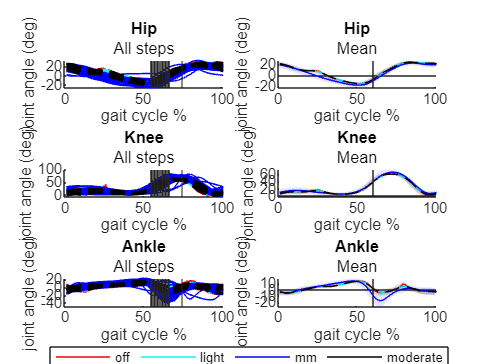

test


kneePlotStruct = struct();
HipPlotStruct = struct();
AnklePlotStruct = struct();

kneePlotStruct.("id") = 4;
HipPlotStruct.("id")  = 2;
AnklePlotStruct.("id") = 6;


for group_idx = 1:group_Count
    group = groups{ group_idx };

    %FootOffIndices
    footOffs.("mean").(group) = analysis.( group ).("LT").("KneeFlexion_Mean_FootOff");
    footOffs.("Normalized").(group) = analysis.( group ).("LT").("KneeFlexion_Normalized_FootOff");

    for functionality_idx = 1:length( functionality )
        func = functionality( functionality_idx );
        dataStruct = buildPlotStruct( analysis.( group ).( "LT" ), func ); %we assume that LT is our Ipsilateral side...

        if functionality_idx == 1 %"KneeFlexion"
            kneePlotStruct.( group ) = dataStruct;
        elseif functionality_idx == 2 %"HipFlexion"
            HipPlotStruct.( group ) = dataStruct;
        elseif functionality_idx == 3 %"AnkleDorsiFlexion"
            AnklePlotStruct.( group ) = dataStruct;
        end

    end
end
plotStruct = struct("HipMean",HipPlotStruct,"KneeMean", kneePlotStruct, "AnkleMean", AnklePlotStruct,"HipFlexion_Normalized",struct(),"KneeFlexion_Normalized",struct(),"AnkleDorsiflexion_Normalized",struct());

%get normalized values as well

for group_idx = 1:group_Count
    group = groups{ group_idx };
    side_ = "LT";
    for plotFieldName_idx = 1:length(functionality)
        thisField = functionality(plotFieldName_idx) + "_Normalized";

        plotStruct.(thisField).(group) = analysis.(group).(side).(thisField);

        %set ids for Plot
        if plotFieldName_idx == 1
            plotStruct.(thisField).("id") = 3;
        elseif plotFieldName_idx == 2
            plotStruct.(thisField).("id") = 1;
        elseif plotFieldName_idx == 3
            plotStruct.(thisField).("id") = 5;
        end

    end
end

countSubplotBoxes = size(fieldnames(plotStruct),1);

fieldNamesPlot = string(fieldnames(plotStruct));
% colorMap = ['g','b','g','r'];

% Assuming group_Count and groups are defined somewhere above this code
legendItems = cell(6, group_Count); % Initialize legendItems as a cell array

for i = 1:6 % 6 boxes in figure
    for ii = 1:group_Count
        curGrp = groups{ii};
        legendItems{i,ii} = string(curGrp); % Assign string to cell array directly
    end
end

% If you want to create a single legend for all items, you might flatten the cell array
% But since each cell already contains a string, you don't need to convert them to cellstr
flatLegendItems = reshape(legendItems.', 1, []); % Flatten the array for legend use if needed



% Define groups and their corresponding colors
% groups = {'light', 'mm', 'moderate', 'off'};
colorMap = {'r', 'c', 'b', 'k'};
colorRGBMap =  [ 1 0 0 ; 0 1 1 ; 0 0 1 ; 0 0 0 ];


f = figure('Name',"MP vs. MyoMotion");


% % First, create all subplots without plotting data to establish layout
% for subplotBoxes = 1:countSubplotBoxes
%     subplot(3,2,subplotBoxes);
% end

% Plot the actual data in each subplot
for subplotBoxes = 1:countSubplotBoxes
    ax = subplot(3,2,subplotBoxes);
    hold on;
%ghost plots for a better legend layout. the colors below are also used in
%legend ideally only call these qws once, not 6 times. but it is what it
%is...

%Change colors of the legend here...
    qw{1} = plot(nan, 'r');
    qw{2} = plot(nan, 'c');
    qw{3} = plot(nan, 'b');
    qw{4} = plot(nan, 'k'); 
    
    for plotFieldName_idx = 1:length(fieldNamesPlot)
        if getfield(plotStruct.(fieldNamesPlot{plotFieldName_idx}), "id") == subplotBoxes %ids are hardcoded => fixed order for each signal type 
            curFieldName = fieldNamesPlot{plotFieldName_idx};
            fieldNameSections = splitStringAtCapitalLetter(curFieldName);
            for group_idx = 1:length(groups)
                curColor = colorMap{group_idx};
                curRGBColor = colorRGBMap(group_idx, :);
                curGroup = groups{group_idx};
                elementProperties.LineColors = curColor;
                if curGroup =="moderate"
                    curLineStyle = '--';
                else
                    curLineStyle = '-';
                end

                if mod(subplotBoxes,2) == 0 % right plot side // if (isEvenNumber) 
                    plot( ax , plotStruct.(curFieldName).(curGroup).DataSummary.mean , 'Color', [ curRGBColor , 0.75 ] , 'LineStyle' , curLineStyle );
                    xline(ax, footOffs.mean.(curGroup));
                    Visualizer_CreatePlot_ShadedSeries_Test(ax,plotStruct.(curFieldName).(curGroup),'Shaded (1SD)',elementProperties,"shadingAreaError","hereErrorALARM");
                    %createOutlinesForShadedSeries
                    % shadedAreaOutline_Data = plotStruct.(curFieldName).(curGroup).DataSummary.mean + plotStruct.(curFieldName).(curGroup).DataSummary.sd; 
                    % plot(ax,shadedAreaOutline_Data,curColor,"LineStyle","--");
                    % shadedAreaOutline_Data = plotStruct.(curFieldName).(curGroup).DataSummary.mean - plotStruct.(curFieldName).(curGroup).DataSummary.sd; 
                    % plot(ax,shadedAreaOutline_Data,curColor,"LineStyle","--");


                    title(ax,fieldNameSections{1});
                    subtitle(fieldNameSections{2});
                    xlabel(ax,"gait cycle %");
                    ylabel(ax,"joint angle (deg)");
                else %left plot side // isOddNumber
                    fieldNameSections{2} = erase(fieldNameSections{2},"_");
                    plot(ax, plotStruct.(curFieldName).(curGroup), 'Color', [ curRGBColor , 0.2 ] , 'LineStyle' , curLineStyle , 'LineWidth' , 0.2 );
                    xline(ax, footOffs.Normalized.(curGroup));
                    xlabel(ax,"gait cycle %");
                    ylabel(ax,"joint angle (deg)");
                    title(ax,[fieldNameSections{1}]); %{2} just says Flexion, not needed {3}= Normalized
                    subtitle("All steps");
                    % alpha(ax,0.02);
                end
            end
            break;
        else
            disp("id not found");
        end
    end
    hold off;
end



legend([qw{:}], {'light','mm','moderate', 'off'}, 'location', 'bestoutside')


% Add a global legend
legend1 = legend(groups, 'Location', 'bestoutside');
set(legend1,...
    'Position',[0.414977493795633 0.00657203737683669 0.199479168256124 0.025641026124995],...
    'Orientation','horizontal');
disp("test")

%
% for group_ind = 1:group_Count
%       group = groups { group_ind }
%       for functionality_idx = 1:length(functionality)
%           meanFunc = functionality( functionality_idx ) + "_Mean";
%           normFunc = functionality( functionality_idx ) + "_Normalized";
%           subplotMean_ID = plotStruct.( normFunc ).( "id" )
%       end
% end

% plotType = 'Shaded (2SD)';
% %
% errMsg = 'error: ';
% %
% 
% areaColor = ''; %e.g 'r' 'y' 'c' et cetera
% 
% plotElementProperties= struct();
% plotElementProperties.LineColors = areaColor;
%
% plotAxis = axes('Position',[0.13 0.11 0.775 0.815],'Box','on');



% [ eH , p , err ] = Visualizer_CreatePlot_ShadedSeries_Test(plotAxis, dataStruct , plotType , plotElementProperties , 0 , errMsg);

## SAVING FIGURE (f) AS VECTOR PDF! 

exportgraphics(f, 'pipelineCurves.pdf' , 'ContentType', 'vector');

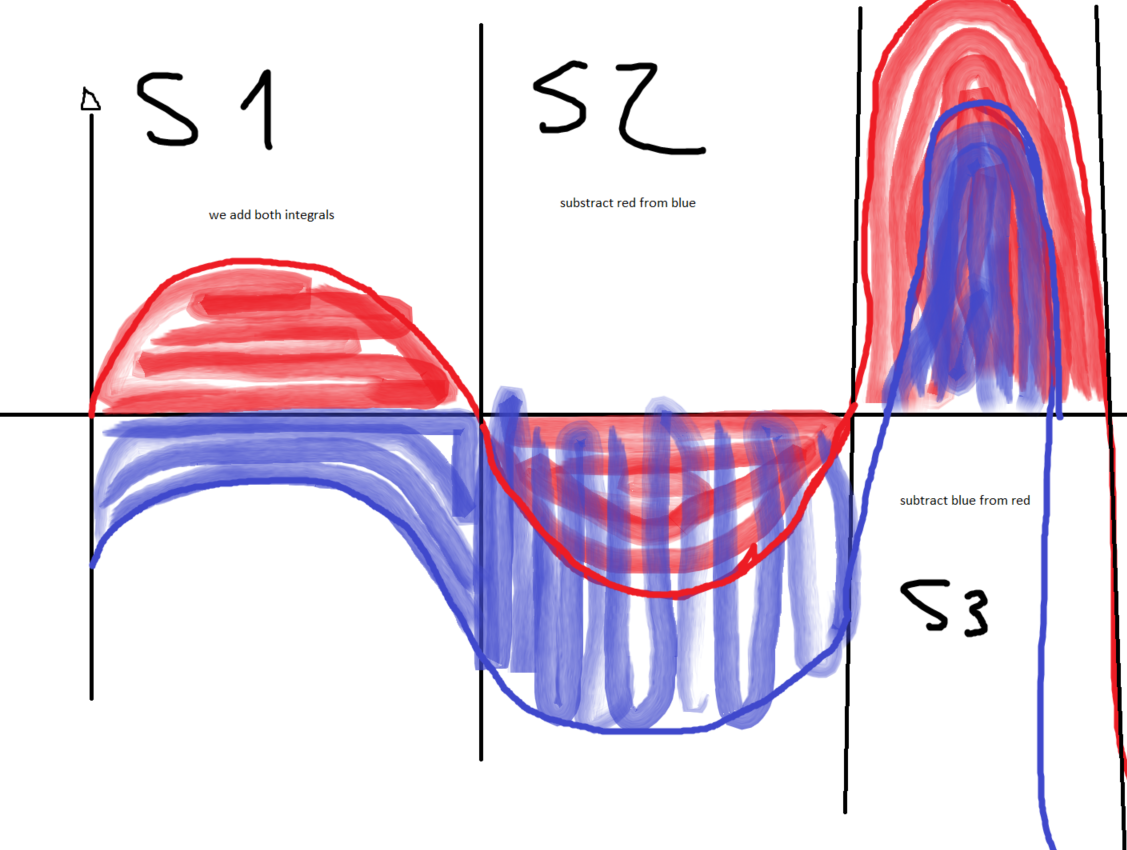

scenarios 

s1 = add both integrals 

s2 = subtract red from blue integral

s3 = subtract blue from red integral

shaded areas / fill with integrals? 